clear variables; close all; clc;

## Practical 6 2022 - Principal Component Analysis

We are going to make Principal Component Analysis models of a metabolomics dataset which studies how adapting the proportion of barley grain in cow's food affects the metabolites in the fluid in the cow's stomachs (Rumen fluid).  The data is taken from this paper; [https://link.springer.com/article/10.1007/s11306-010-0227-6](https://link.springer.com/article/10.1007/s11306-010-0227-6)

The data is in cow_diet.csv 

Load the data and look at the table.

cow_diet = readtable("cow_diet.csv", 'VariableNamingRule','preserve');
sample = cow_diet.Sample;
diet = cow_diet.Diet;

cow_diet = removevars(cow_diet,["Sample","Diet"])

cow_diet = 39×47 table
    1,3-D    3-HB     3-HP    3-PP     Acetate    Acetoacetate    Alanine    Aspartate    Benzoate    Butyrate    Cadaverine    Caffeine    Choline    Dimethylamine    Ethanol    Ferulate    Formate    Glutamate    Glycerol    Glycine    Histidine    Hypoxanthine    Isobutyrate    Isoleucine    Isovalerate    Lactate    Leucine    Lysine    Maltose    Methanol    Methylamine    NDMA     Nicotinate    Phen

names = cow_diet.Properties.VariableNames;

Notice the samples are in the rows, and the metabolites are in the columns.  

Some columns also contain other information, like the sample name or the percentage of barley grain in that cow's diet (diet column).

### PCA of the raw data

Before we can make a PCA model, we need to extract a numerical matrix with just the values for each metabolite in each sample;

M = table2array(cow_diet)

M = 1.0e+04 *

    0.0003         0    0.0011    0.0312    4.3721    0.0013    0.0091    0.0063    0.0023    0.5653    0.0021    0.0012    0.0003    0.0002    0.0059         0    0.0002    0.0153    0.0024    0.0042    0.0035    0.0043    0.0808    0.0044    0.0622    0.0051    0.0044    0.0049    0.0016    0.0007    0.0003    0.0029    0.0011    0.0141    0.0044    0.0056    1.1371    0.0101    0.0041    0.0019    0.0054    0.0984    0.0033    0.0032    0.0577    0.0219         0
    0.0002    0.0048    0.0036    0.0466    5.5084    0.0052    0.0153    0.0134    0.0024    0.9454    0.0059    0.0011    0.0010    0.0006    0.0173         0    0.0008    0.0299    0.0100    0.0084    0.0011    0.0094    0.1253    0.0174    0.1086    0.0074    0.0075    0.0048    0.0048    0.0018    0.0017    0.0038    0.0025    0.0279    0.0037    0.0090    1.9909    0.0107    0.0035    0.0031    0.0079    0.1650    0.0076    0.0054    0.0496    0.0383         0
    0.0003    0.0034    0.0019    0.0363   

First we will make a PCA model of the unnormalised, unscaled data - we can use this model to detect any outliers that need to be removed before further processing.

Use the **pca **function to build a PCA model.  Check the help, and extract the coefficients, scores, variances in each pc, and total variance explained.

[coeffs, score, ~, ~, explained, ~] = pca(M);

### Visualising the PCA model of the raw data

For the first two principal components (PCs) 

- make a scores plot colouring the samples by group - labelling the axes with the variance explained in each PC.

- a loadings plot - showing the weights of each metabolite in each principal component 

- a scree plot for all PCs showing how the cumulative variance explained increase as the number of PCs in the model increases (check the function **pareto**).

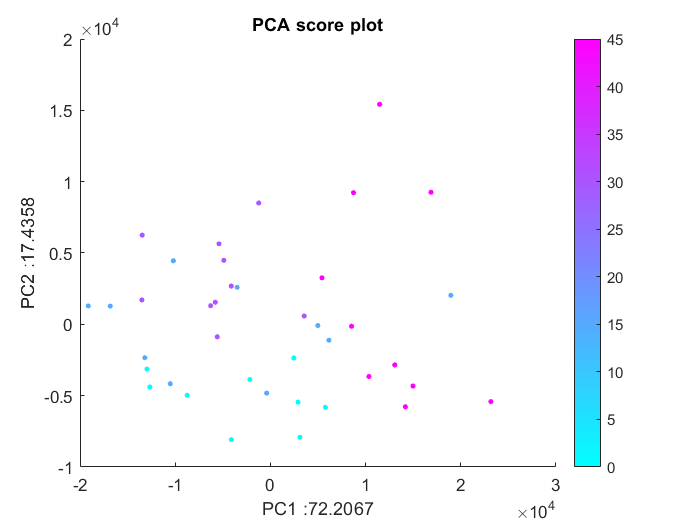

figure;
scatter(score(:,1),score(:,2),10,diet,'filled');
hold on; colorbar; colormap cool;

xlabel(strcat("PC1 :", num2str(explained(1))));
ylabel(strcat("PC2 :", num2str(explained(2))));
title("PCA score plot");
hold off;

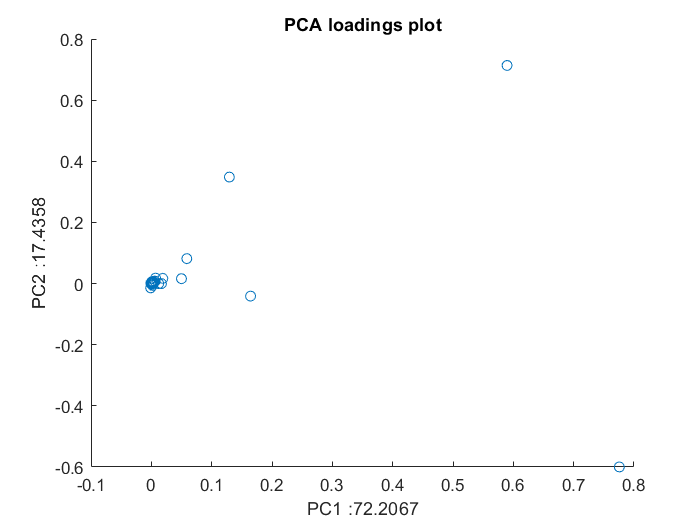

scatter(coeffs(:,1), coeffs(:,2));
xlabel(strcat("PC1 :", num2str(explained(1))));
ylabel(strcat("PC2 :", num2str(explained(2))));
title("PCA loadings plot");

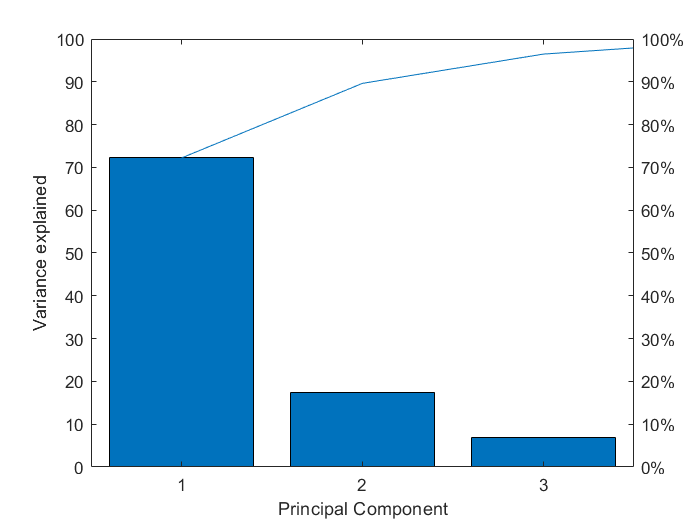

pareto(explained);
xlabel("Principal Component"); ylabel("Variance explained");

Looking at these plots do you see any outlier samples which need to be excluded?

### Normalising the data with median fold change normalisation

Now we need to normalise our data as this is metabolomics data we will use median fold change normalisation. Check the slides from the gene expression lecture for the algorithm and code it up.  

*NB. Some metabolites have 0 values, which can give NANs when you divide by these values, which will then lead to issues later on.  Either add a very very small amount to every metabolite to get rid of the zeros, or filter out the NANs which are created from the division when you look for the most probable quotient (the median fold change). * 

Visualise the data before and after normalisation to check that the normalisation has worked.

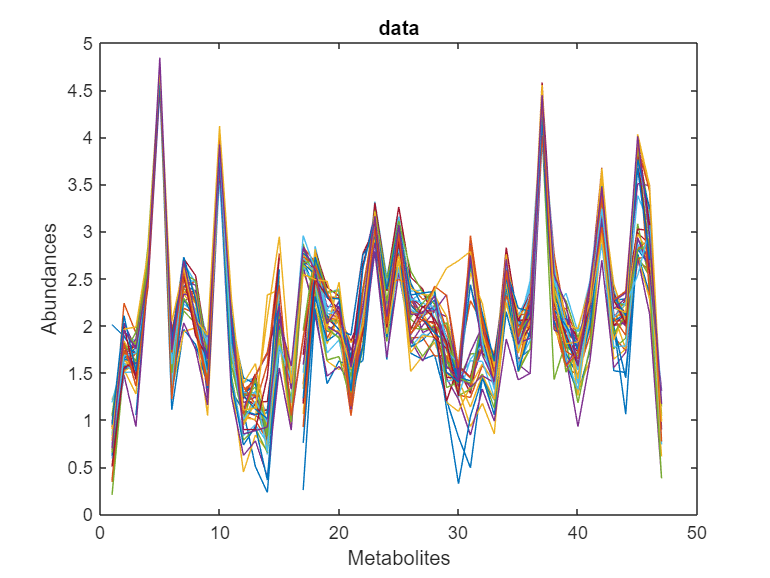

nM = median_fold(M);
figure; plot(1:47, log10(M));
xlabel('Metabolites'); ylabel('Abundances'); title("data");

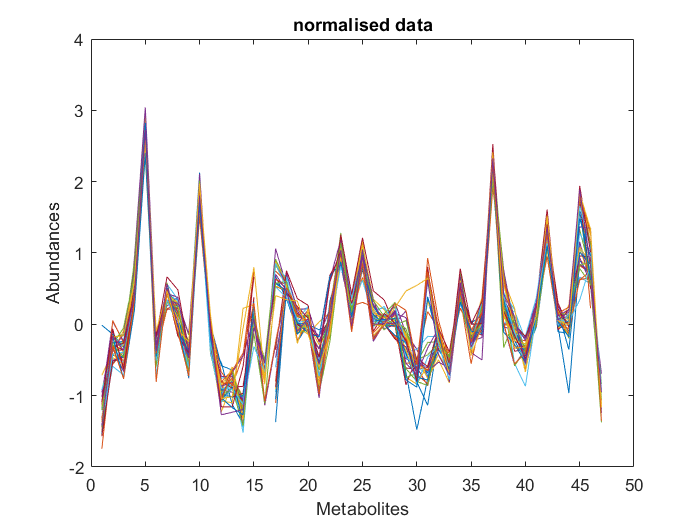

figure; plot(1:47, log10(nM));
xlabel('Metabolites'); ylabel('Abundances'); title("normalised data");

### PCA of the normalised data

Now we can build a PCA model of the normalised data - make the same set of plots again.

[nCoeff, nScore, ~, ~, nExplained, ~] = pca(nM);

Looking at the loadings plots - which metabolites are important for this model?  Why are these metabolites important? (data science not biology)

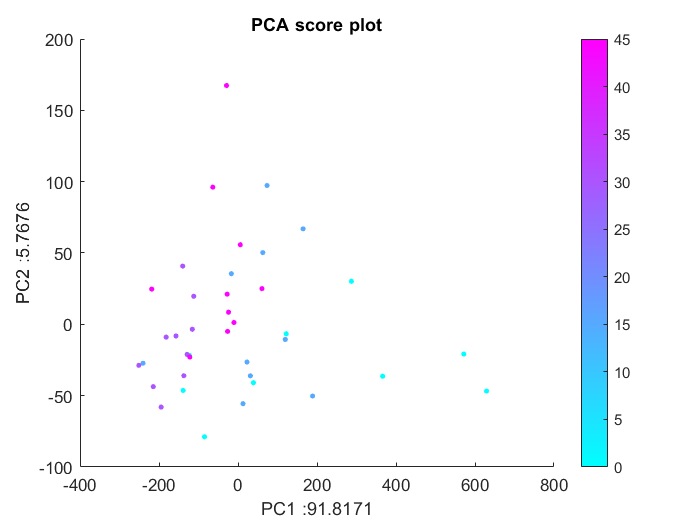

figure;
scatter(nScore(:,1),nScore(:,2),10,diet,'filled');
hold on; colorbar; colormap cool;

xlabel(strcat("PC1 :", num2str(nExplained(1))));
ylabel(strcat("PC2 :", num2str(nExplained(2))));
title("PCA score plot");
hold off;

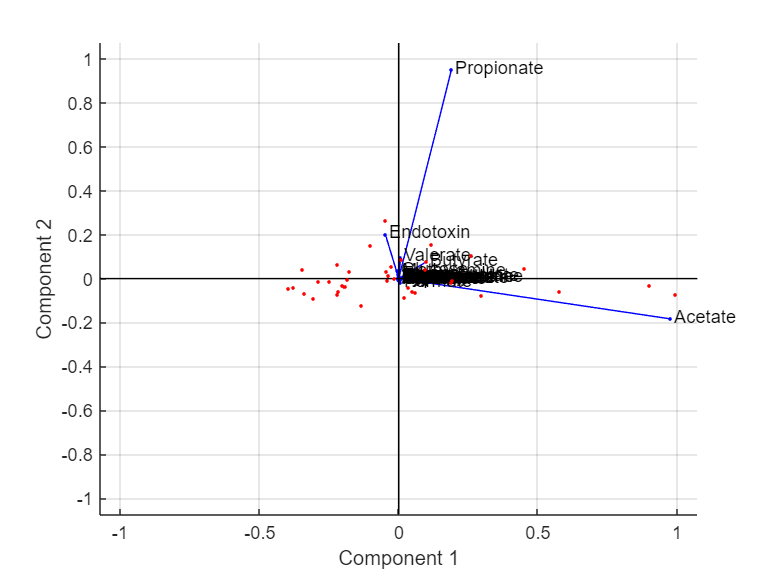

biplot(nCoeff(:,1:2), "Scores",nScore(:,1:2),'VarLabels',names)

scatter(sCoeff(:,1), sCoeff(:,2));

Reference to a cleared variable sCoeff.

xlabel(strcat("PC1 :", num2str(sExplained(1))));
ylabel(strcat("PC2 :", num2str(sExplained(2))));
title("PCA loadings plot");
pareto(sExplained);
xlabel("Principal Component"); ylabel("Variance explained");

### Scaling the data

If we want all our variables to have equal weight in the model, we need to scale the data - make each metabolite have a mean of 0 and a variance of 1.  This is called Unit Variance scaling, or sometimes autoscaling or z-scores.  We do this on the normalised data.

We can use the **zscore** function for this (from the statistics and machine learning toolbox).

sM = zscore(nM);

### PCA of the scaled data

Make one final PCA model of the scaled data and make the standard plots.

[sCoeff, sScore, sLatent, sTsquared, sExplained, sMu] = pca(sM);

scatter(sScore(:,1),sScore(:,2),10,diet,'filled');
hold on; colorbar; colormap cool;
xlabel(strcat("PC1 :", num2str(sExplained(1))));
ylabel(strcat("PC2 :", num2str(sExplained(2))));
title("PCA score plot");
hold off;
biplot(sCoeff(:,1:2),'scores', sScore(:,1:2),'VarLabels',names)

scatter(sCoeff(:,1), sCoeff(:,2));
xlabel(strcat("PC1 :", num2str(sExplained(1))));
ylabel(strcat("PC2 :", num2str(sExplained(2))));
title("PCA loadings plot");
pareto(sExplained);
xlabel("Principal Component"); ylabel("Variance explained");

Using these plots - which metabolites would you expect to be high in the 45% barley fed cows?

function [nM] =  median_fold(M)
    sz = size(M);
    nM = zeros(sz);
    nM(M==0) = 1e-6;
    ref = median(M,2);
    nM = M./ref;
    nM(isnan(nM)) = 0;
end